test de modulation avec un faux signal (cosinus)

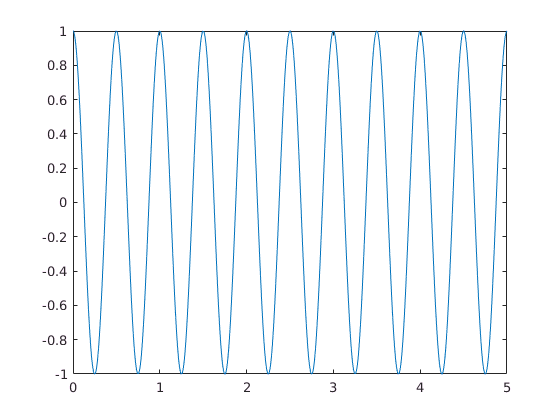

T=5;
Fe=96000;
t=0:1/Fe:T-(1/Fe);

voix1= cos(2*pi*2*t);
plot(t,voix1);

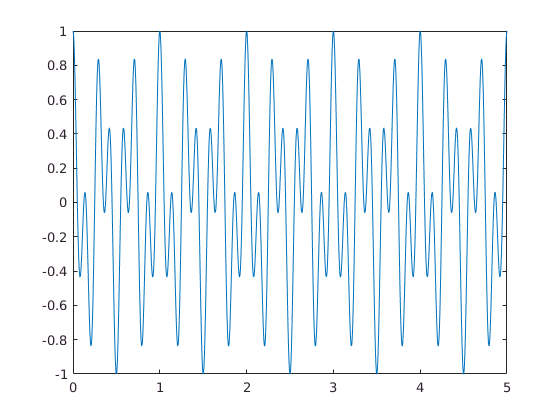

mod_voix1=voix1.*cos(2*pi*5*t);
plot(t,mod_voix1);

une fois la voix créée, on passe en Fourier.

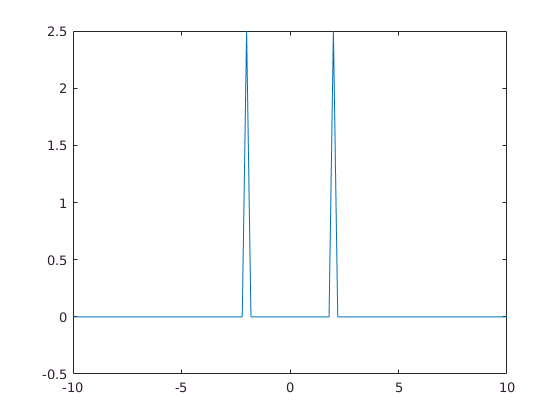

[Fvoix1,T]=TransFourier(voix1,t);
[Fmod_voix1,T]=TransFourier(mod_voix1,t);
plot(T,Fvoix1);xlim([-10,10]);

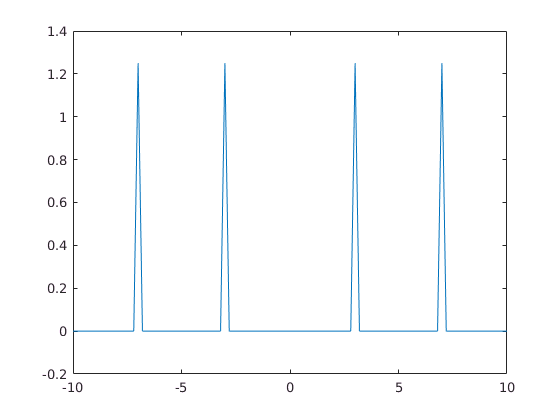

plot(T,Fmod_voix1);xlim([-10,10]);

ok pour la modulation

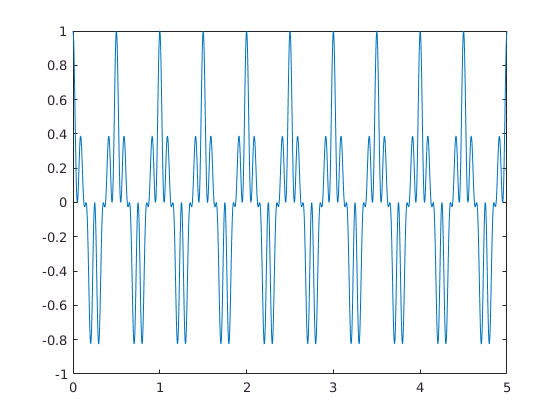

demod_voix1=mod_voix1.*cos(2*pi*5*t);
plot(t,demod_voix1);

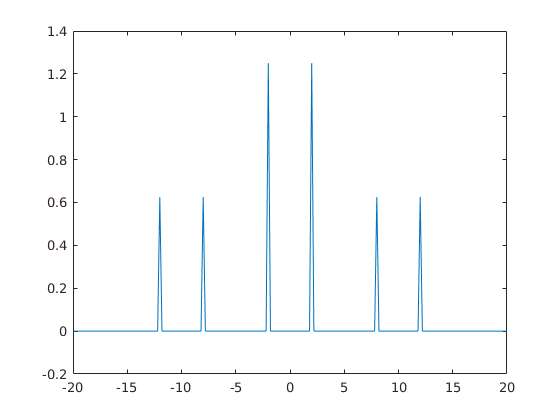

[Fdemod_voix1,Freq]=TransFourier(demod_voix1,t);
plot(Freq,Fdemod_voix1);xlim([-20,20]);

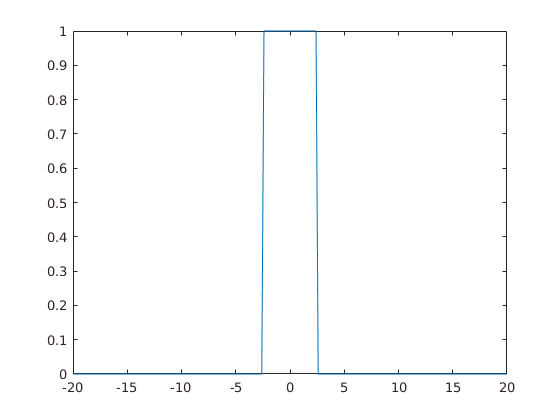

filtre=porte(Freq/5);
plot(Freq,filtre);xlim([-20,20]);

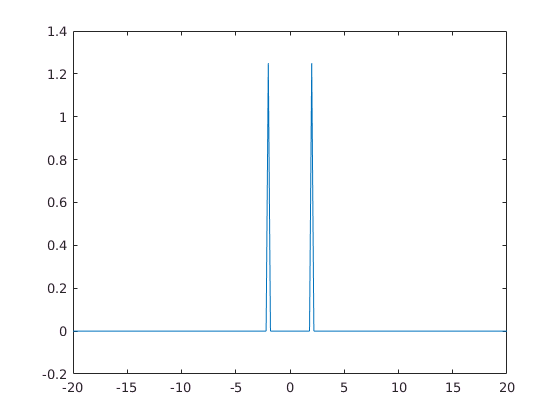

F_voix1=Fdemod_voix1.*filtre;
plot(Freq,F_voix1);xlim([-20,20]);

on retrouve la transformer de Fourier du signal de base.

%[voix_1,t]=TransFourierInv(F_voix1,Freq);
%plot(t,voix_1);

Création du fichier audio de 5s:

%[test,audio,t]=RecordModulation(96000,5);
[audio,Fe]=audioread('crapaud.wav');
%plot(t,audio);

Filtrage de la voix par un filtre passe bas:

F_coupure=3000;
[audio_filtre]=PasseBas(audio,Fe,F_coupure);

modulation de la voix

F_mod=1000;
T=5;
Fe=96000;
t=0:1/Fe:T-(1/Fe);

mod_audio=audio'.*cos(2*pi*F_mod*t); %on transpose le vecteur audio
plot(t,mod_audio);

on demodule le signal:

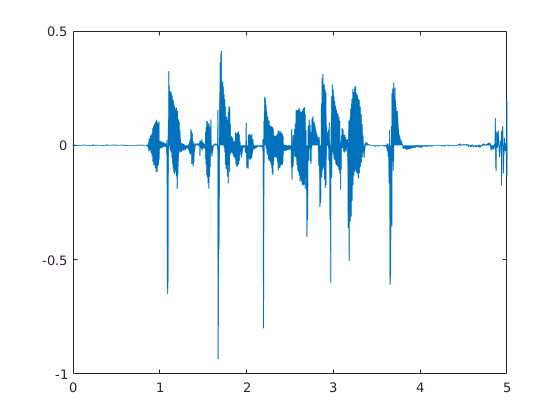

demod_audio=mod_audio.*cos(2*pi*F_mod*t);
figure(2);
plot(t,demod_audio);

il faut refiltrer le signal:

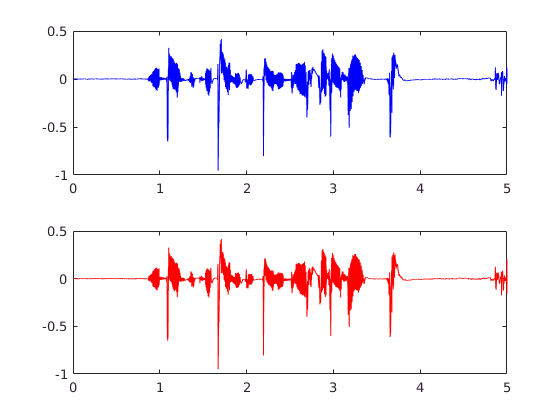

[filtre_demod_audio]=PasseBas(demod_audio,Fe,F_coupure);
figure(1);
final_audio=2*filtre_demod_audio;
subplot(211);plot(t,final_audio,'blue');
subplot(212);plot(t,audio,'r');

on ecoute l'audio final:

soundsc(mod_audio,Fe);